## Appendix

### Part a)

**Step 1:** Generate the input signal x[n]

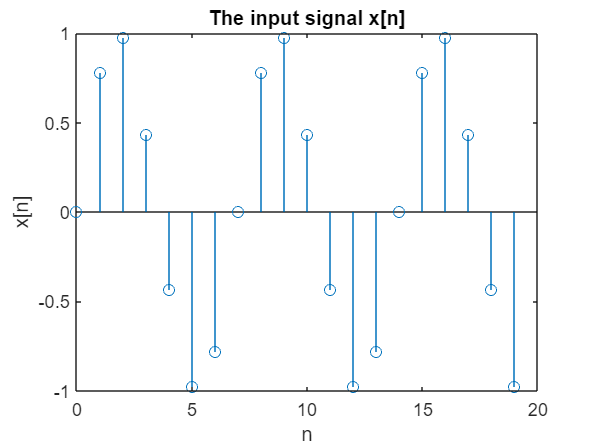

N = 20;
n = 0:1:N-1;
x = sin(2*pi*n/7);
figure;
stem(n,x);
xlabel('n');
ylabel('x[n]');
title('The input signal x[n]');

**Step 2: **Generate and plot the impulse response h[n]

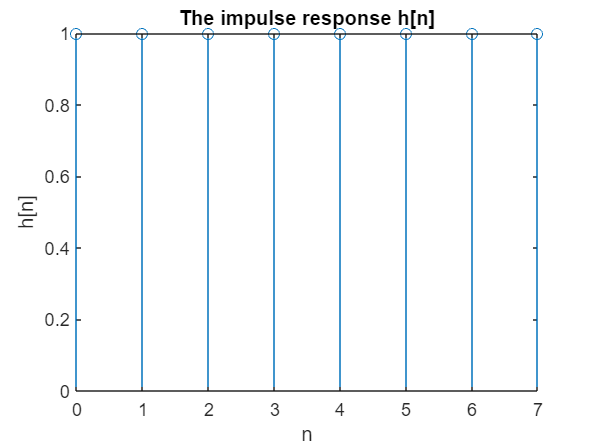

L = N-12;
h = ones(1,L);
figure;
stem(0:L-1,h);
xlabel('n');
ylabel('h[n]');
title('The impulse response h[n]');

**Step 3: **Time-reversed impulse response h[-n]

h_reversed = flip(h);

**Step 4: **Zero-padding 

x_padded = [zeros(1,L-1) x  zeros(1,L-1)];

**Step 5: **Evaluate the convolution sum 

y = zeros(1,N+L-1);
for i=1:N+L-1
    y(i) = x_padded(i:i+L-1)*h_reversed'; 
end

**Step 6: **Plot the output signal y[n]

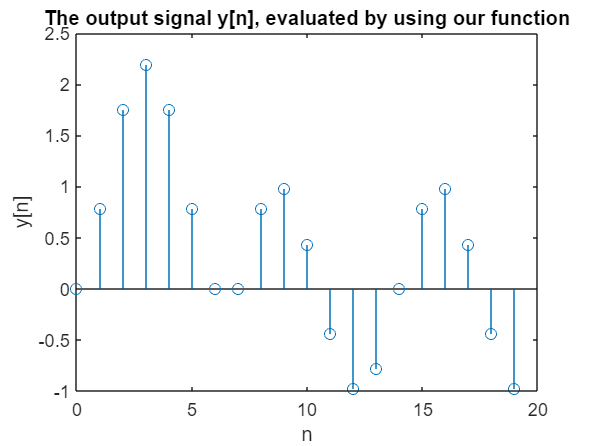

y = y(1:N);
figure;
stem(n,y);
xlabel('n');
ylabel('y[n]');
title('The output signal y[n], evaluated by using our function');

**Step 7: **MATLAB built-in convolution function 

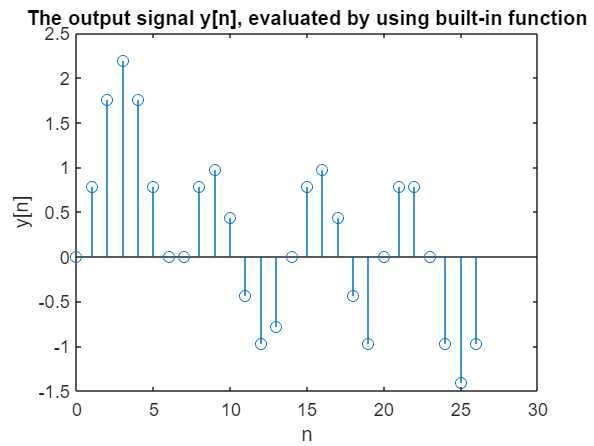

y = conv(x,h);
figure;
stem(0:N+L-2,y);
xlabel('n');
ylabel('y[n]');
ylabel('y[n]');
title('The output signal y[n], evaluated by using built-in function');

### Part b)

**Step 1:** Generate random input signal x[n]

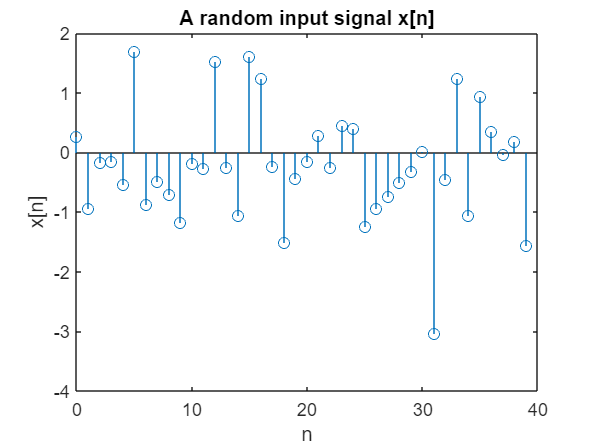

N = 40;
n = 0:1:N-1;
x = randn(1,N);
figure;
stem(n,x);
title('A random input signal x[n]');
xlabel('n');
ylabel('x[n]');

**Step 2: **Plot the output signal y[n] for different values of L

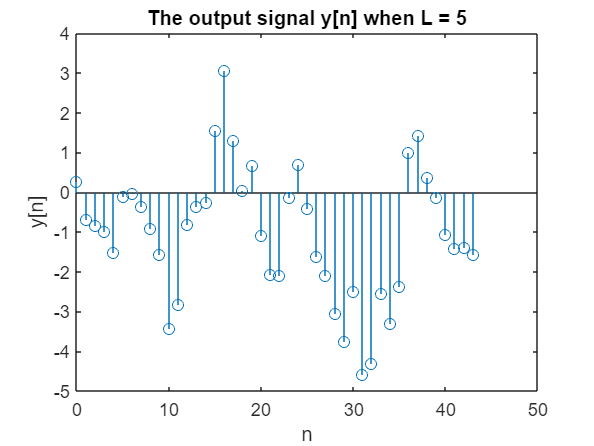

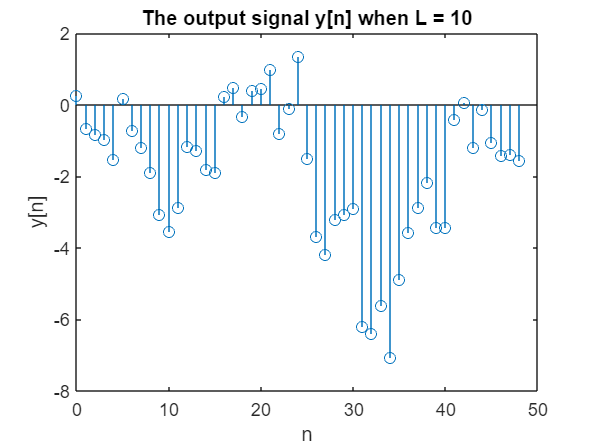

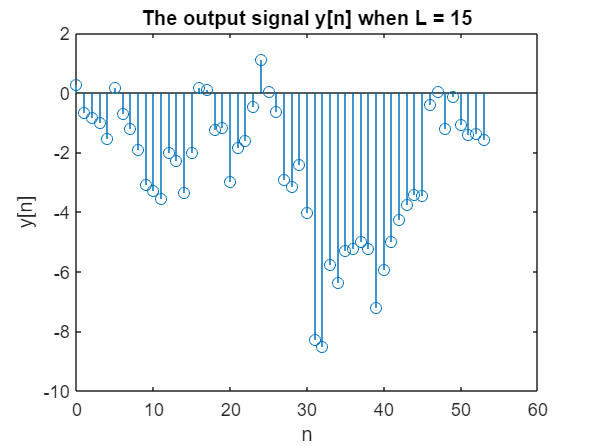

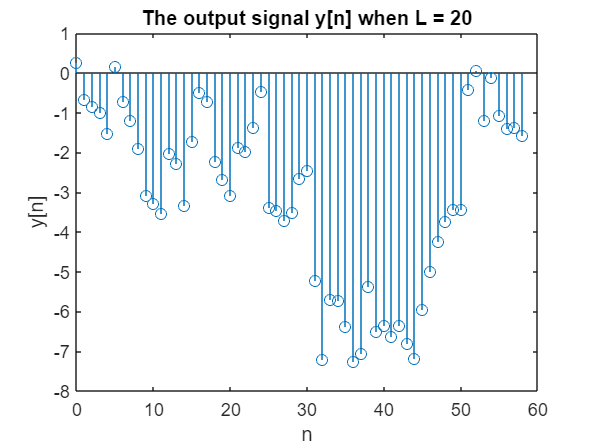

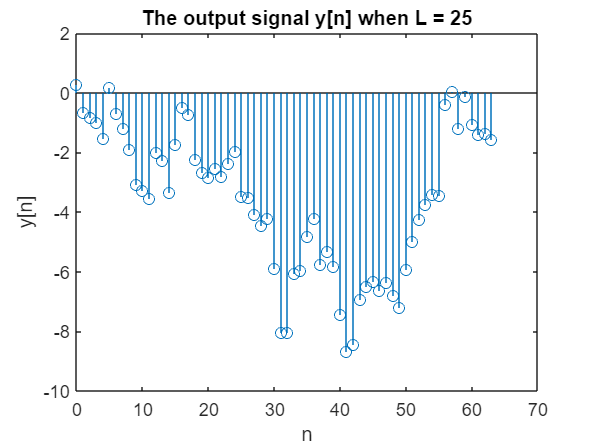

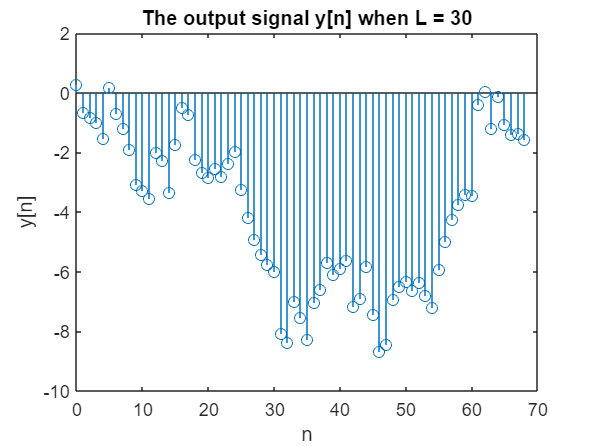

for l=5:5:30
    L = l;
    h = ones(1,L);
    y = conv(x,h);
    figure;
    stem(0:N+L-2,y);
    title(['The output signal y[n] when L = ',num2str(L)]);
    xlabel('n');
    ylabel('y[n]');
end